clear, close all

Lorenz system is a system of ordinary differential equations that have chaotic parameter values and initial conditions. Lorenz system is nonlinear, non-periodic,  3-D and deterministic. This system of ODEs are:

dx/dt= σ(y-x)

dy/dt= x(ρ-z)-y

dz/dt= xy-βz)

The stableness of the system is determined by checking the eigenvalues of the Jacobian  at each equilibrium point. If the real parts of all eigenvalues are negative, the Lorenz system is stable. If this eigenvalue condition is not satisfied then the system unstable. By assigning parameters σ = 10, ρ = 28, β = 8/3 to the system of ODEs, the eigenvalue condition is not satisfied. Hence the system is unstable. An unstable Lorenz system exhibits exponential growth and therefore accentuate the effect of noise. This dynamic system with chaotic solutions exhibit a succession of period with stable and unstable behavior. 

## PART I: Understanding Lorenz

Here we will simulate Lorenz’s equation from 0 to 4.0 at a time interval of 0.002. The initial guess of the equilibrium point is [x0 = -3.3, y0 = 3.0, z0 = 10.5]. In this part of the code we observe the state space of the Lorenz system and trace the positions of equilibrium point at each time step. The state-space of the model is described in the figure below:

randn('seed',123)

% For these given parameters the system exhbits chaotic behavior
sig = 10; rho = 28; b = 8/3;

% lorenz system is a system of 3 ordinary differential equations
% Y(1) = x, Y(2) = y, Y(3) = z
Lorenz_equation = @(t,Y,sig,rho,b) ...
    [sig*(Y(2)-Y(1)); rho*Y(1)-Y(2)-Y(1)*Y(3); Y(1)*Y(2)-b*Y(3)];

Lorenz_Jacobian = @(Y, sig, rho, b) ... 
    [-sig, sig, 0; rho-Y(3), -1, -Y(1); Y(2), Y(1), -b];

D = b*rho-b;
% if D < 0 there is only one equilibrium point in the origin
if D<0
    ne = 1;
    xe = 0; ye = xe; ze = xe^2/b;
    disp('There is one simple equilibrium point:')
    disp(['x = ',num2str(xe),'  y = ',num2str(ye), '  z = ', num2str(ze)])
% a pitchfork bifurcation occurs at D =0
elseif D==0
    ne = 1;
    xe = 0; ye = xe; ze = xe^2/b;
    disp('There is one triple equilibrium point:')
    disp(['x = ',num2str(xe),'  y = ',num2str(ye), '  z = ', num2str(ze)])
% 2 additional critical points appear
else D>0
    ne = 3;
    xe = [0;sqrt(D);-sqrt(D)]; ye = xe; ze = xe.^2/b;
    disp('There are three equilibrium points:')
    disp(['x = ',num2str(xe(1)),'  y = ',num2str(ye(1)), '  z = ', num2str(ze(1))])
    disp(['x = ',num2str(xe(2)),'  y = ',num2str(ye(2)), '  z = ', num2str(ze(2))])
    disp(['x = ',num2str(xe(3)),'  y = ',num2str(ye(3)), '  z = ', num2str(ze(3))])
end

ans = logical
   1


There are three equilibrium points:


x = 0  y = 0  z = 0


x = 8.4853  y = 8.4853  z = 27


x = -8.4853  y = -8.4853  z = 27



% The eigenvalues of the Jacobian at each equilibrium point determine
% whether the equilibrium is stable or not. The real parts of all
% eigenvalues have to be negatives in order to be stable.
for k = 1:ne
    J = Lorenz_Jacobian([xe(k), ye(k), ze(k)], sig, rho, b);
    Le = eig(J);
    if (real(Le(1))<0)&(real(Le(2))<0)&(real(Le(3))<0)
        disp(['Equilibrium at point ',num2str(k),' is stable.'])
    elseif real(Le(1))*real(Le(2))*real(Le(3))==0
        disp(['Equilibrium at point ',num2str(k),' is (neutrally) unstable.'])
    else
        disp(['Equilibrium at point ',num2str(k),' is unstable.'])
    end
end

Equilibrium at point 1 is unstable.


Equilibrium at point 2 is unstable.


Equilibrium at point 3 is unstable.


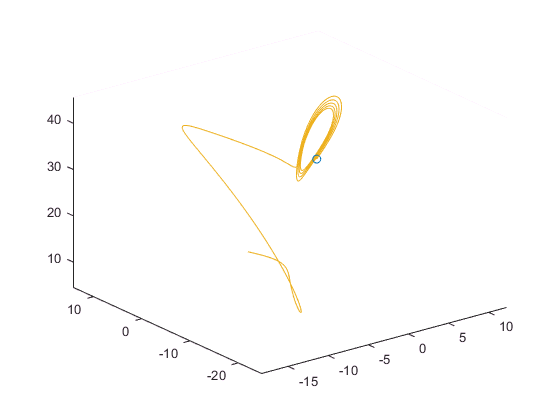


% Take an initial guess
x0  = -3.3; y0 = 3.0; z0 = 10.5;

time = 4.0;

options = odeset('RelTol', 1.E-7, 'AbsTol', 1.E-7);
[T,Y] = ode45(Lorenz_equation, [0:0.002:time], [x0;y0;z0], options, sig,rho,b);


% plot the state space of lorenz equation
figure(1), clf
comet3(Y(:,1), Y(:,2), Y(:,3)) % trace curve through the points [xi,yi,zi]

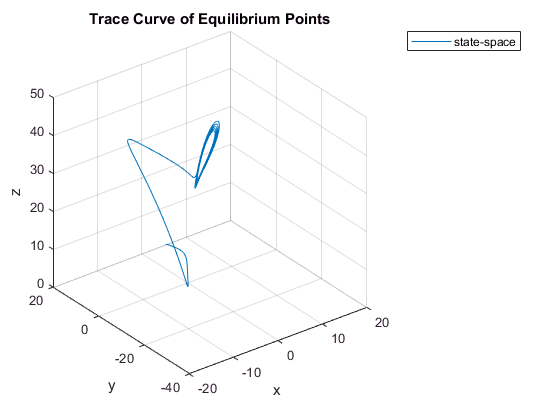

plot3(Y(:,1), Y(:,2), Y(:,3),'DisplayName','state-space'), grid on
xlabel('x'), ylabel('y'), zlabel('z');title('Trace Curve of Equilibrium Points');
legend('show');

disp(['at time  ', num2str(T(length(T))), '   the final point is:  '])

at time  4   the final point is:  


disp(Y(length(Y),:))

    5.1955    2.8291   26.6374



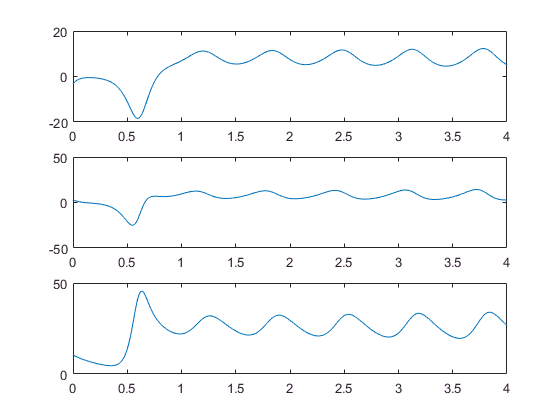



figure(2), clf
subplot(3,1,1)
plot(T,Y(:,1))
subplot(3,1,2)
plot(T,Y(:,2))
subplot(3,1,3)
plot(T,Y(:,3))

## PART II: Lorenz with noise

After solving the state space system to get the nonlinear function Φ that describes the system, the program adds white noise to the state space. The noise is added to the program from time 0 to time 2.0, at an interval of 0.01 and the level of the noise is determined by the covariance matrix Q.  The state evolution equation in discrete time can be written as:


$$x\left(t+\Delta t\right)=\phi \left(x\left(t\right)+w\left(t\right)\right)$$


Where $\phi$ is a nonlinear equation, and w is a white noise process(0,Q).

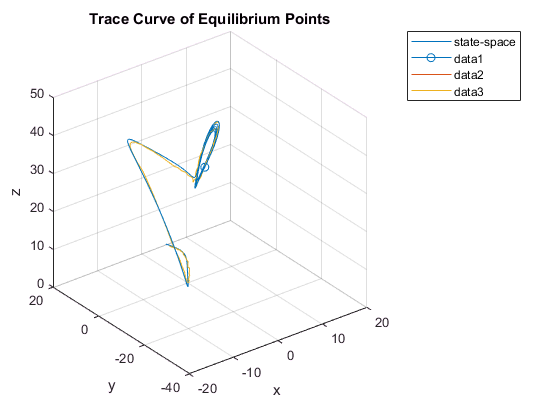

%generate data for "actual" system with noise
Dt = 0.01;
Q = 0.01*eye(3); %small variance
% Q = 1*eye(3); %large variance
B = chol(Q)'; 
k_steps = 200;
Xt = zeros(3,k_steps);
Xt0 = [x0; y0; z0]; % we will use the same initial point as the deterministic simulation

% in this part we will simulate the lorenz equations while adding
% white noise from time 0 to time 2 at a time interval of 0.01
for k = 1:k_steps
    Sol = ode45(Lorenz_equation, [0 Dt], Xt0, ...
        options, sig,rho,b);
    Xt(:,k) = deval(Sol, Dt) + B*randn(3,1);
    Xt0 = Xt(:,k);
end
% Plot the "actual" data (state + deterministic + noise)
figure(1), hold on
comet3(Xt(1,:), Xt(2,:), Xt(3,:));
hold off

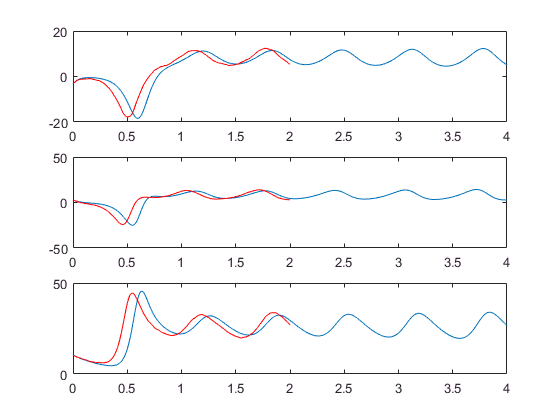


figure(2)
subplot(3,1,1)
hold on
plot([Dt:Dt:k_steps*Dt],Xt(1,:),'r','DisplayName','actual equilibrium x');
hold off
subplot(3,1,2)
hold on
plot([Dt:Dt:k_steps*Dt],Xt(2,:),'r','DisplayName','actual equilibrium y');
hold off
subplot(3,1,3)
hold on
plot([Dt:Dt:k_steps*Dt],Xt(3,:),'r','DisplayName','actual equilibrium z');
hold off

In this problem the observations are made at x coordinate only, so H = [1;0;0]. A random probabilistically defined noise term is added to the observations. The relationship between H and y follow:


$$y=\mathbf{Hx}+v$$


% generate data/observations, only the x coordinates are observed
% sqrt(r)*randn term provide the noise to the system
H = [1 0 0]; R = 1;
for k = 1:k_steps
    y_data(k) = H*Xt(:,k) + sqrt(R)*randn; 
end

## Part III. Extended Kalman filter.

Invert the observations in order to trace the actual equilibrium points from time 0 to time 2.0.

**Prediction:**

The state transition matrix computed through this approximation is $\phi =\left(I+\Delta t\text{ }\mathbf{A}\right)$ , for sufficiently small this is close to the exact solution  $\phi =\mathrm{exp}\left(\Delta t\text{ }\mathbf{A}\right)$. **A** is the Jacobian matrix of the system of equations that describe the state space of Lorenz. We obtain the prediction of equilibrium points through the non-linear equation, and obtain the prediction of the covariance matrix through the state-transition matrix:


$$\hat{x} \left(t+\Delta t\text{ }|\text{ }t\right)=\phi \text{ }\left(\hat{x} \left(t\text{ }|\text{ }t\right)\right)$$



$$\Sigma \left(t+\Delta t\text{ }|\text{ }t\right)=\phi \left(t\right)\Sigma \left(t\text{ }|\text{ }t\right)\phi^T \left(t\right)+Q$$


**Updating:**

The residue (difference between observation and prediction):

     
$$\mathrm{residue}=y-\mathbf{H}\hat{x} \left(t+\Delta t\text{ }|\text{ }t\right)$$


Residue variance is:


$$\left.\Sigma 2{\left(t+\text{∆}t \right|}t+\text{∆}t\right)=H\Sigma {\left(t+\text{∆}t \right|}t\right)H^T +R$$


Linear feedback coefficient K is known as the **Kalman gain**, it can be expressed as :


$$K\text{ }\left(t+\Delta t\right)=\Sigma \left(t+\Delta t\text{ }|\text{ }t\right){\mathbf{H}}^T \Sigma 2^{-1}$$


and the posteior covariance afte time-step:


$$\left.\Sigma {\left(t+\text{∆}t \right|}t+\text{∆}t\right)=\Sigma {\left(t+\text{∆}t \right|}t\right)- \Sigma {\left(t+\text{∆}t \right|}t\right){\mathbf{H}}^T K^T$$


And our new prediction after Kalman correction comes out to be:


$$\left.\hat{x} {\left(t+\text{∆}t \right|}t+\text{∆}t\right)=\hat{x} {\left(t+\text{∆}t \right|}t\right)+K*residue$$


to $\left.\hat{x} {\left(t+\mathrm{∆}t \right|}t+\mathrm{∆}t\right)$ becomees the current point K(t | t) in the next iteration and we will repeat the prediction and update rule described above. 

Q = 10000*Q; 
X_hat = zeros(3,k_steps);
res = zeros(1,k_steps);
sig2 = zeros(1,k_steps);
stableq = zeros(1,k_steps);
X_hat0 = [x0; y0; z0];  % we will still use the same initial point
SIG0 = zeros(3); 

for k = 1:k_steps
    disp(num2str(k))
    %prediction
    Sol = ode45(Lorenz_equation, [0 Dt], X_hat0, ...
        options, sig,rho,b);
    X_hat(:,k) = deval(Sol, Dt);
    
    A = Lorenz_Jacobian(X_hat0, sig, rho, b);
        %stability of underlying dynamic system, if the real part of
        %eigenvalue of lorenz Jacobian is negative, the nthe system is stable
        d = eig(A);
        if max(real(d))<0
            stableq(k) = 1;
        end
   
    PHI = expm(A*Dt);   %PHI is the approximated transition matrix
    SIG = PHI*SIG0*PHI' + Q; % specifically covariance sig(k+1|k)
    
    % update
    sig2(:,k) = H*SIG*H'+R;     % residue variance
    K = SIG*H'*inv(sig2(:,k));  % Kalman gain
    SIG = SIG - K*H*SIG;        % specifically SIG(k+1|k+1), posterior covariance
    res(:,k) = y_data(k)-H*X_hat(:,k);  % residue = y - H*x_hat
    X_hat(:,k) = X_hat(:,k) + K*res(:,k); % prediction after Kalman correction
    
    X_hat0 = X_hat(:,k);
    SIG0 = SIG; 
        %%stability of feedback system           
%             d = eig(PHI-K*H*PHI);
%             if max(real(d))<1
%                 stableq(k) = 1;
%             end
end

1


2


3


4


5


6


7


8


9


10


11


12


13


14


15


16


17


18


19


20


21


22


23


24


25


26


27


28


29


30


31


32


33


34


35


36


37


38


39


40


41


42


43


44


45


46


47


48


49


50


51


52


53


54


55


56


57


58


59


60


61


62


63


64


65


66


67


68


69


70


71


72


73


74


75


76


77


78


79


80


81


82


83


84


85


86


87


88


89


90


91


92


93


94


95


96


97


98


99


100


101


102


103


104


105


106


107


108


109


110


111


112


113


114


115


116


117


118


119


120


121


122


123


124


125


126


127


128


129


130


131


132


133


134


135


136


137


138


139


140


141


142


143


144


145


146


147


148


149


150


151


152


153


154


155


156


157


158


159


160


161


162


163


164


165


166


167


168


169


170


171


172


173


174


175


176


177


178


179


180


181


182


183


184


185


186


187


188


189


190


191


192


193


194


195


196


197


198


199


200


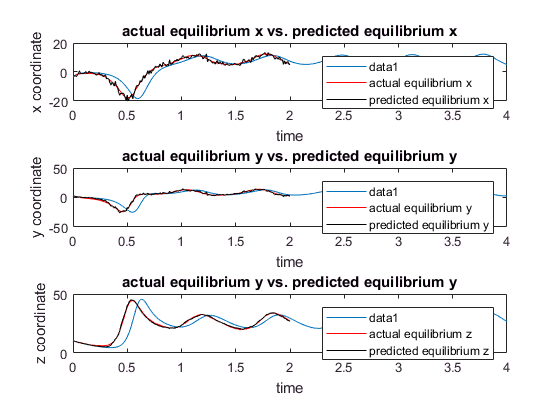


% In figure 2 we plot the prediction vs. actual
figure(2)
subplot(3,1,1)
hold on
plot([Dt:Dt:k_steps*Dt],X_hat(1,:),'k','DisplayName','predicted equilibrium x')
xlabel('time'); ylabel('x coordinate');hold off; legend('show');
title('actual equilibrium x vs. predicted equilibrium x')

subplot(3,1,2)
hold on
plot([Dt:Dt:k_steps*Dt],X_hat(2,:),'k','DisplayName','predicted equilibrium y')
xlabel('time'); ylabel('y coordinate');hold off; legend('show');
title('actual equilibrium y vs. predicted equilibrium y')

subplot(3,1,3)
hold on
plot([Dt:Dt:k_steps*Dt],X_hat(3,:),'k','DisplayName','predicted equilibrium z')
xlabel('time'); ylabel('z coordinate'); hold off; legend('show');
title('actual equilibrium y vs. predicted equilibrium y')

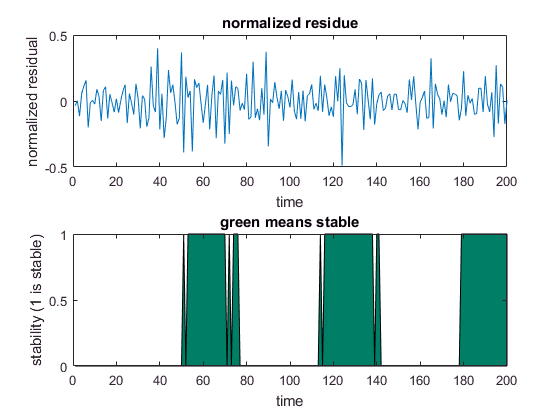


% figure 3 plots the normalized residue and the underlying system stability
figure(3), clf
subplot(2,1,1)
plot(1:k_steps, res./sqrt(sig2))
xlabel('time'); ylabel('normalized residual'); title('normalized residue');
subplot(2,1,2)
area(stableq)
colormap summer
title('green means stable')
xlabel('time'); ylabel('stability (1 is stable)');

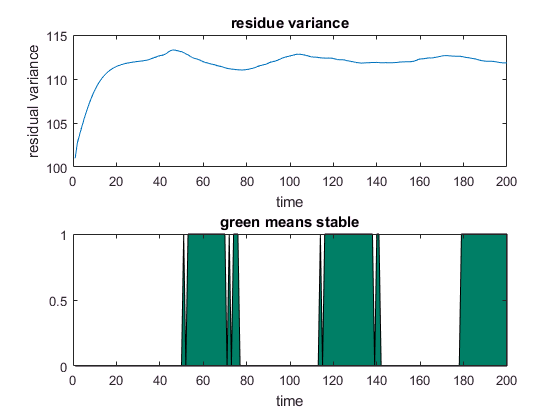


% figure 4 plots the residual variance and underlying system stability
figure(4), clf
subplot(2,1,1)
plot(1:k_steps, sig2)
xlabel('time');ylabel('residual variance'); title('residue variance');
subplot(2,1,2)
area(stableq)
colormap summer
title('green means stable');
xlabel('time');

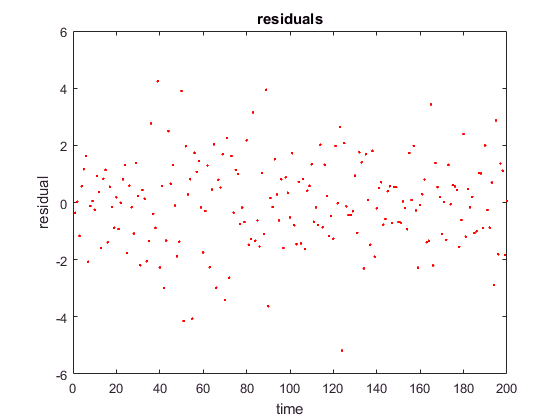


% This part performs the post-factum check on the estimator.
figure(6), clf
plot(1:k_steps, res,'r.')
title('residuals'), xlabel('time'), ylabel('residual');


mres = mean(res)

mres = -0.0163

sdres = std(res)

sdres = 1.5186

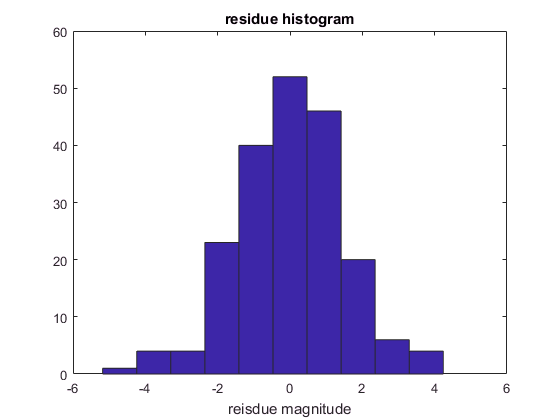

figure(7), hist(res);
xlabel('reisdue magnitude');;title('residue histogram')

corrcoef([res(2:end)', res(1:end-1)'])

ans =     1.0000   -0.4758
   -0.4758    1.0000
